## Zero analysis

The analysis of zeros is less straight-forward than the analysis of the poles of the system, because their effects are less pronounced. Zeros contribute to

- the transient behavior of the response,

- the magnitude of the response, and

- the response to different input frequencies.

   **Activity.** Consider the simple system:

    
$$G(s) = \frac{ s-z_0}{s+1}$$


Adjust the location of the zero using the slider and observe the changes to the response.

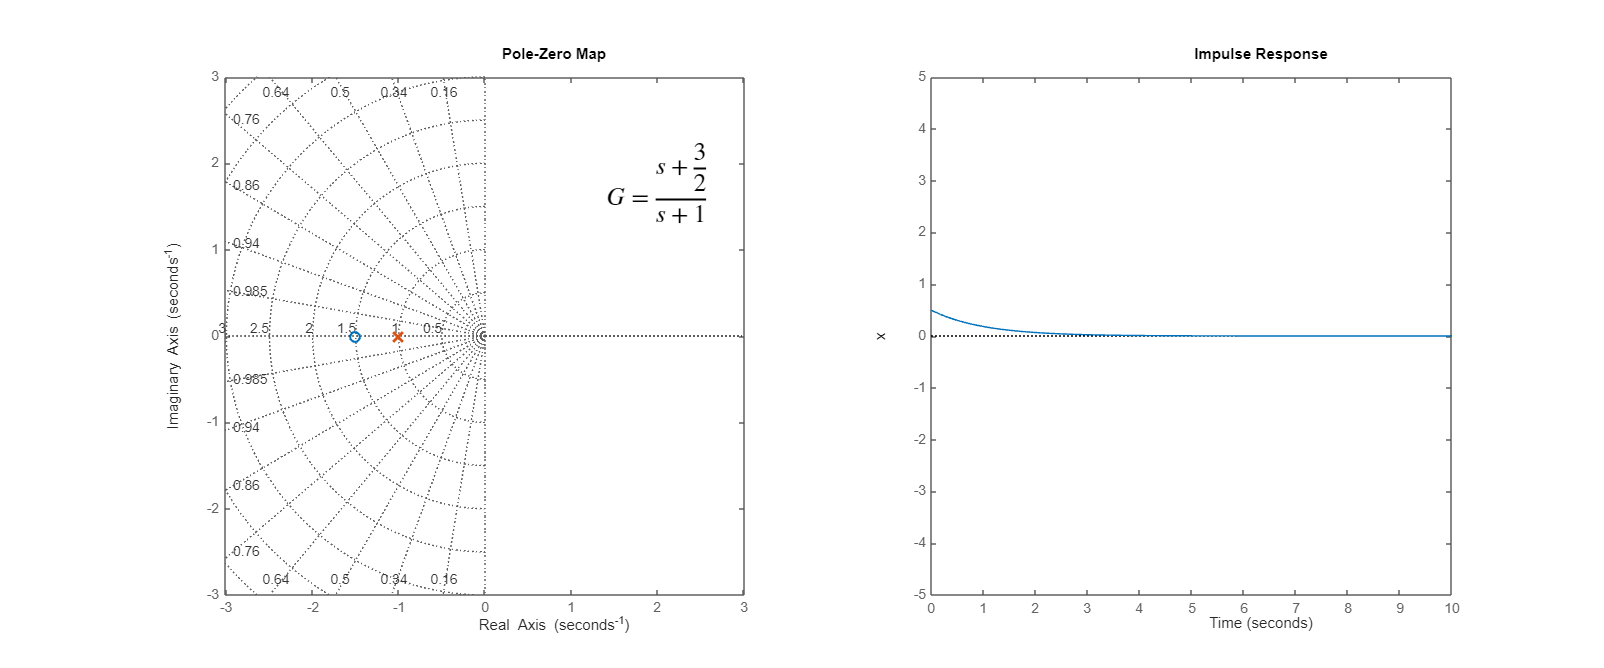

z0 = -1.5; % Position of the zero
G = tf([1 -z0],[1 1]);           % The transfer function G(s)
axlim1 = [-3 3 -3 3];            % Axis limits for the first graph
axlim2 = [0 10 -5 5];            % Axis limits for the second graph
pzmapAndImpulse(G,axlim1,axlim2) % Generates the plot

**  Reflect.** 

- Is the stability or long-term behavior of the system affected by the zero location?

- How is the transient response affected by the zero?

- Does the system become unstable when the zero is in the right-half plane?

- What happens as the zero approaches the pole?

   **Activity. **In this activity, you will visually explore the relationship between transfer function zeros and time-domain responses. You will inspect the step responses of

        
$$G = \frac{s-z_0}{s^2 + 2s + 2}$$


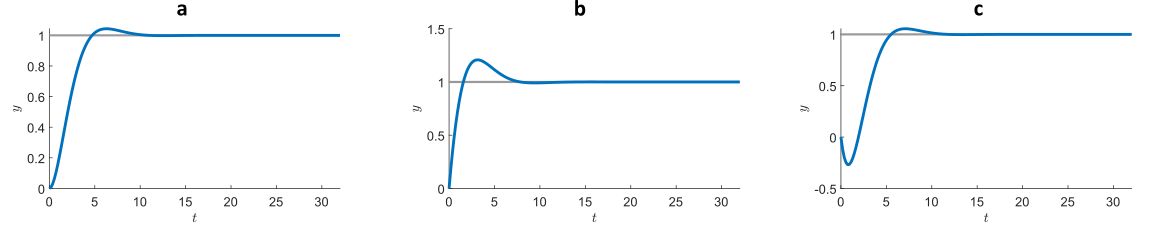

`Zeros used to generate the plots: `

`a: 0,  b: -2,  c: 1.5`

function pzmapAndImpulse(G,axlim1,axlim2)
% Plots the poles and impulse response together
    figure("Position",[0 0 1200 500])    
    
    % Pole-zero map plot
    subplot(1,2,1)
    pzmap(G,"b")
    grid on
    axis(axlim1)
    axis equal
    syms s
    Htex = newline + "\ " + newline + "$G = " + latex(poly2sym(G.num{1},s)/poly2sym(G.denom{1},s)) + "$ \quad";
    text(axlim1(2),axlim1(4),Htex,"Interpreter","Latex","HorizontalAlignment","right",...
        "FontSize",18,"VerticalAlignment","top")
    lineObjs = findobj(gca,"Type","Line");   
    set(lineObjs(3),"MarkerSize",10,"LineWidth",2,"Color",[0.8500 0.3250 0.0980]);           
    set(lineObjs(2),"MarkerSize",7,"LineWidth",1.5,"Color",[0 0.4470 0.7410]);   
    
    % Impulse-response plot
    subplot(1,2,2)
    impulse(G,10) 
    axis(axlim2)
    ylabel("x")
end
